% Step 1: Read the audio
[xx, fs] = audioread('SunshineSquare.wav');
xx = xx(:);  % Ensure column vector
duration = length(xx) / fs;
fprintf('Audio duration: %.2f seconds\n', duration);

Audio duration: 10.80 seconds


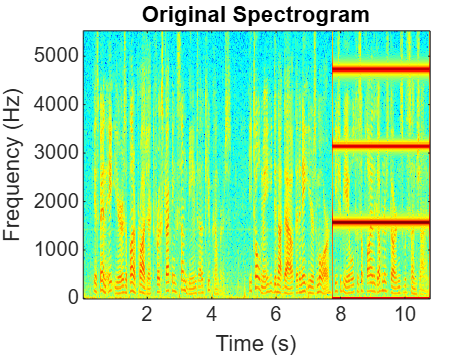


% Step 2: Show spectrogram and visually inspect tones
figure;
specgram(xx, 512, fs);
title('Original Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

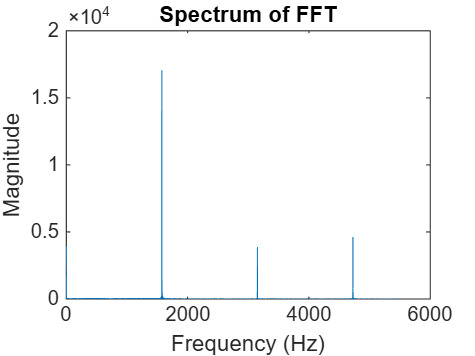


% Step 3: Extract audio segment from 8 to 10.8 seconds
t_start = 8;
t_end = 10.8;
idx_range = round(t_start * fs) : round(t_end * fs);
x_target = xx(idx_range);

% Step 4: Use FFT to find three dominant tone frequencies
N = length(x_target);
X = abs(fft(x_target));
f = (0:N-1)*(fs/N);

% Only use positive frequencies
X_half = X(1:floor(N/2));
f_half = f(1:floor(N/2));

plot(f_half, X_half);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of FFT');


% Define the three frequency bands to search
ranges = [1000 2000; 2000 4000; 4000 fs/2];
notch_freqs = zeros(1, 3);  % Initialize

for i = 1:3
    f_min = ranges(i,1);
    f_max = ranges(i,2);

    % Find indices within the specified frequency range
    idx_range = find(f_half >= f_min & f_half <= f_max);

    % Get index of maximum magnitude in this range
    [~, idx_local_max] = max(X_half(idx_range));
    real_idx = idx_range(idx_local_max);
    notch_freqs(i) = f_half(real_idx);
    notch_freqs(i) = round(f_half(real_idx));
end

disp('Identified tone frequencies to remove (Hz):');

Identified tone frequencies to remove (Hz):


disp(notch_freqs');

        1575
        3150
        4725



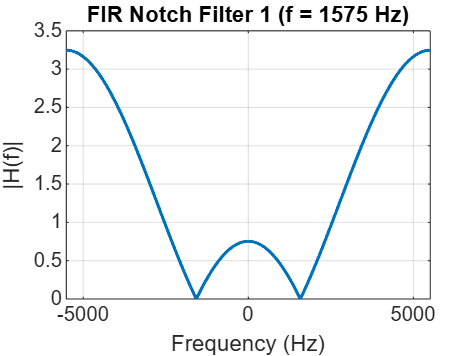

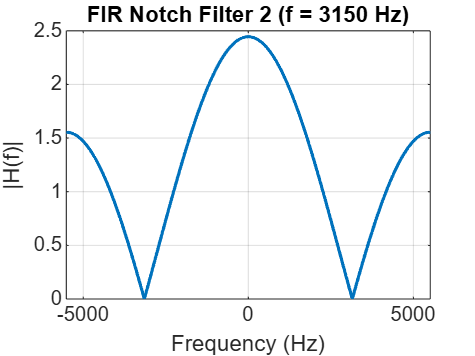

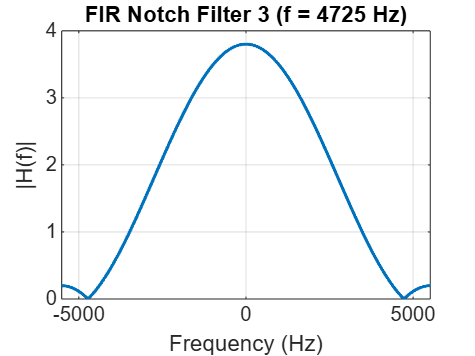


% Step 5: Design FIR notch filters and apply them
filtered_audio = xx;
for i = 1:length(notch_freqs)
    % Convert to digital angular frequency
    w = 2 * pi * notch_freqs(i) / fs;

    % Compute FIR coefficients
    A = -2 * cos(w);
    h = [1, A, 1];

    % Apply filter (FIR, so a = 1)
    filtered_audio = filter(h, 1, filtered_audio);

    % Plot frequency response of the filter
    figure;
    w_axis = linspace(-pi, pi, 1024);
    H = freqz(h, 1, w_axis);
    f_axis = w_axis / (2*pi) * fs;

    plot(f_axis, abs(H), 'LineWidth', 1.5);
    grid on;
    title(['FIR Notch Filter ', num2str(i), ' (f = ', num2str(notch_freqs(i)), ' Hz)']);
    xlabel('Frequency (Hz)');
    ylabel('|H(f)|');
    xlim([-fs/2, fs/2]); 
end

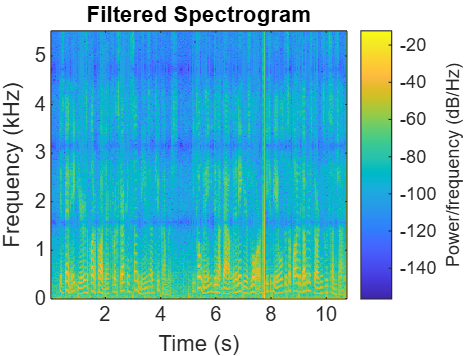


% Step 6: Show spectrogram of filtered signal
figure;
spectrogram(filtered_audio, 1024, 512, 1024, fs, 'yaxis');
title('Filtered Spectrogram');


% Step 7: Save and play the filtered audio
audiowrite('filtered_fft.wav', filtered_audio, fs);

disp('Filtered audio saved as filtered_fft.wav');

Filtered audio saved as filtered_fft.wav



[xx, fs] = audioread('filtered_fft.wav');
sound(xx, fs);

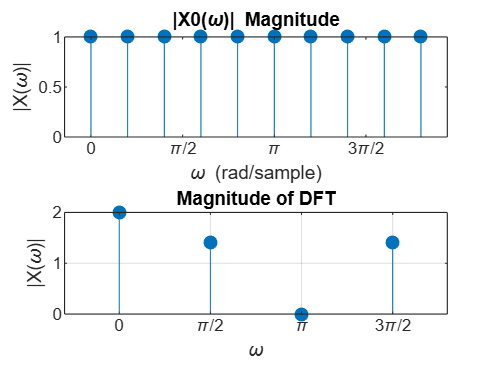

x = [1 1 0 0];

% 計算 FFT（4-point DFT）
X = fft(x);

% 頻率軸（離散頻率）
N = length(x);
omega = (0:N-1) * 2*pi/N;  % 離散頻率對應到 0 ~ 2π

% 畫出 magnitude
stem(omega, abs(X), 'filled');
xlabel('\omega');
ylabel('|X(\omega)|');
title('Magnitude of DFT');
xticks([0 pi/2 pi 3*pi/2 2*pi]);
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'});
grid on;